### 1.  line continuation operator 

  一般在编辑器里一行代码太长写不下了，用...表示续行，下一行的代码和上一行是连着的

cmap = [1 1 1; ...%  1 - white - 空地
    0 0 0; ...% 2 - black - 障碍
    1 0 0; ...% 3 - red - 已搜索过的地方
    0 0 1; ...% 4 - blue - 下次搜索备选中心
    0 1 0; ...% 5 - green - 起始点
    1 1 0;...% 6 - yellow -  到目标点的路径
    1 0 1];% 7 - -  目标点
A = cmap;

### 2.image(x,y,C)

绘制网格，image(x,y,C),如果x,y是一个数，表示起始坐标（坐标间距为1）；

如果为一个二维数组，表示起止坐标，间距自适应计算

如果为一个多维数组，用起止的元素数，表示起止坐标，间距自适应计算

image(1.5, 1.5, cmap); %绘制网格，image(x,y,C),如果x,y是一个数，表示起始坐标（坐标间距为1）；
%如果为一个二维数组，表示起止坐标，间距自适应计算
%如果为一个多维数组，用起止的元素数，表示起止坐标，间距自适应计算

### 3.`drawnow`

修改图形对象并且需要在屏幕上立即查看这次更新

drawnow %基础使用
drawnow limitrate %跳过更新以产生更快的动画,将更新数量限制为每秒 20 帧，距离上一次改变50ms内的新改变将会被遗弃

### 4.计时器

tic;
toc;

延时功能代码段

tic;
time = 1 %延时时间
for t = 0.001:0.1:time% 初始时刻：精度分辨率：结束时刻
    while toc < t
    end
end

### 5.min

M = min(A);%返回数组的最小元素。


- 如果 `A` 是向量，则 `min``(A)` 返回 `A` 的最小值。

- 如果 `A` 为矩阵，则 `min``(A)` 是包含每一列的最小值的行向量。

- 如果 `A` 是多维数组，则 `min``(A)` 沿大小不等于 `1` 的第一个数组维度计算，并将这些元素视为向量。此维度的大小将变为 `1`，而所有其他维度的大小保持不变。如果 `A` 是第一个维度为 `0` 的空数组，则 `min``(A)` 返回与 `A` 大小相同的空数组。

[M,I] = min(A(:));

 M 返回A 的最小值，I返回最小值的索引。如果最大值出现多次，则 min 返回对应于第一次出现位置的索引。

[M,I] = min(A);%A为二维矩阵

M返回一个行向量，每一列都是A的每一列的最小值。

I也返回一个行向量，对应的是M每一个元素在A中的索引。

### 6.ind2sub

从线性索引映射到坐标索引

注意：对于二维矩阵，线性索引是从上到下，从左至右，按列排号的。

而矩阵中表示则是按行显示排的

如：

IND = [3 4; 5 6]，结果为

`IND = ``2×2`

`     3     4`

`     5     6`

`对于该函数而言：`

`[I,J] = ind2sub([矩阵],线性索引)`

`在矩阵中，线性索引对应的坐标位置`

IND = [3 4; 5 6];
s = [3,3];
[I,J] = ind2sub(s,IND);
%即

### 7.size

sz = size(A);

返回一个行向量，其元素包含 `A` 的相应维度的长度。例如，如果 `A` 是一个 3×4 矩阵，则 `size(A)` 返回向量 `[3 4]`。

dim = 2;
szdim = size(A,dim);

返回维度 `dim` 的长度。

%[sz1,...,szN] = size(A)

分别返回 `A` 的每个维度的长度。

### 8.

% (neighbor(:,1)>2) + (neighbor(:,1)>nrows) +(neighbor(:,2)>1) + (neighbor(:,2)>ncols )

### 9.矩阵的转置

#### 1.一般转置A.'

A = cmap
AdotStart = A.'

#### 2. 共轭转置 A'

如果是实数，那么与普通转置无区别

AStart = A'

如果是复数

a=[1+1i 2+2i 3+3i;4+4i 5+5i 6+6i]
adotStart = a.'
aStart =a'

注：

求共轭矩阵conj(a)

aConj = conj(a)

#### 3.把矩阵转化为一维矩阵

列矩阵A(:)

行矩阵A(:).'

ACol = A(:)
ARow = A(:).'

### 10.元胞数组

*元胞数组*是一种包含名为*元胞*的索引数据容器的数据类型，其中的每个元胞都可以包含任意类型的数据。元胞数组通常包含文本列表、文本和数字的组合或者不同大小的数值数组。通过将索引括在圆括号 `()` 中可以引用元胞集。使用花括号 `{}` 进行索引来访问元胞的内容。

C = {1,2,3;
     'text',rand(5,10,2),{11; 22; 33}}
C1 = {}
C2 = cell(5)

### 11.uicontrol创建用户界面控件

`c =` `uicontrol` 在当前图窗中创建一个普通按钮（默认用户界面控件），并返回 `UIControl` 对象。如果图窗形不存在，MATLAB® 会创建一个图窗。

一般会指定父对象，为

`c = uicontrol(parent)`

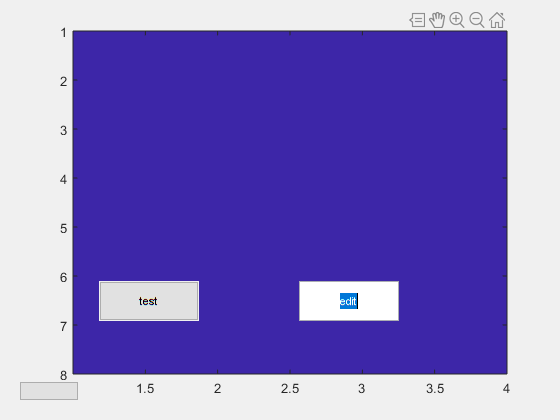

时间已过 0.000050 秒。


time = 1

A =      1     1     1
     0     0     0
     1     0     0
     0     0     1
     0     1     0
     1     1     0
     1     0     1


AdotStart =      1     0     1     0     0     1     1
     1     0     0     0     1     1     0
     1     0     0     1     0     0     1


AStart =      1     0     1     0     0     1     1
     1     0     0     0     1     1     0
     1     0     0     1     0     0     1


a =    1.0000 + 1.0000i   2.0000 + 2.0000i   3.0000 + 3.0000i
   4.0000 + 4.0000i   5.0000 + 5.0000i   6.0000 + 6.0000i


adotStart =    1.0000 + 1.0000i   4.0000 + 4.0000i
   2.0000 + 2.0000i   5.0000 + 5.0000i
   3.0000 + 3.0000i   6.0000 + 6.0000i


aStart =    1.0000 - 1.0000i   4.0000 - 4.0000i
   2.0000 - 2.0000i   5.0000 - 5.0000i
   3.0000 - 3.0000i   6.0000 - 6.0000i


aConj =    1.0000 - 1.0000i   2.0000 - 2.0000i   3.0000 - 3.0000i
   4.0000 - 4.0000i   5.0000 - 5.0000i   6.0000 - 6.0000i


ACol =      1
     0
     1
     0
     0
     1
     1
     1
     0
     0


ARow =      1     0     1     0     0     1     1     1     0     0     0     1     1     0     1     0     0     1     0     0     1


C = 2×3 cell 数组
    {[   1]}    {[          2]}    {[     3]}
    {'text'}    {5×10×2 double}    {3×1 cell}



C1 =

  空的 0×0 cell 数组



C2 = 5×5 cell 数组
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


uic1 =   UIControl - 属性:

              Style: 'pushbutton'
             String: ''
    BackgroundColor: [0.9400 0.9400 0.9400]
           Callback: ''
              Value: 0
           Position: [20 20 60 20]
              Units: 'pixels'

  显示 所有属性


uic2 =   UIControl (test) - 属性:

              Style: 'pushbutton'
             String: 'test'
    BackgroundColor: [0.9400 0.9400 0.9400]
           Callback: ''
              Value: 0
           Position: [100 100 100 40]
              Units: 'pixels'

  显示 所有属性


uic3 =   UIControl (edit) - 属性:

              Style: 'edit'
             String: 'edit'
    BackgroundColor: [0.9400 0.9400 0.9400]
           Callback: ''
              Value: 0
           Position: [300 100 100 40]
              Units: 'pixels'

  显示 所有属性


uic1 = uicontrol
uic2 = uicontrol('Style','pushbutton',"string","test","Position",[100 100 100 40])
uic3 = uicontrol('Style','edit',"string","edit","Position",[300 100 100 40])

`c = ``uicontrol``(`[`Name,Value`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html?searchHighlight=uicontrol&s_tid=doc_srchtitle#namevaluepairarguments)`)` 创建一个用户界面控件，其中包含使用一个或多个名称-值对组参数指定的属性值。例如，`'Style','checkbox'` 会创建一个复选框。

要确保name和value一一对应

典型name有：

`'Style'`

`'String'`

`'Position'`

`'Value'`

[示例](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html#mw_b8f1afcf-de3c-48d4-b18f-4a8109983d42)

`c =` `uicontrol``(`[`parent`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html?searchHighlight=uicontrol&s_tid=doc_srchtitle#mw_aad7ccca-6a5f-4a24-accf-9e356b55a394)`,`[`Name,Value`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html?searchHighlight=uicontrol&s_tid=doc_srchtitle#namevaluepairarguments)`)` 指定用户界面控件的父容器和一个或多个名称-值对组参数。

[示例](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html#mw_5e3681f1-26bc-4abc-b90c-2538445f39f8)

`uicontrol``(`[`uc`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/uicontrol.html?searchHighlight=uicontrol&s_tid=doc_srchtitle#mw_51fe35c7-a16d-4520-87ba-51e5907244d0)`)` 将焦点放在指定的用户界面控件上。

note：uc是刚生成的控件。

uicontrol(uic3)